# data.mat

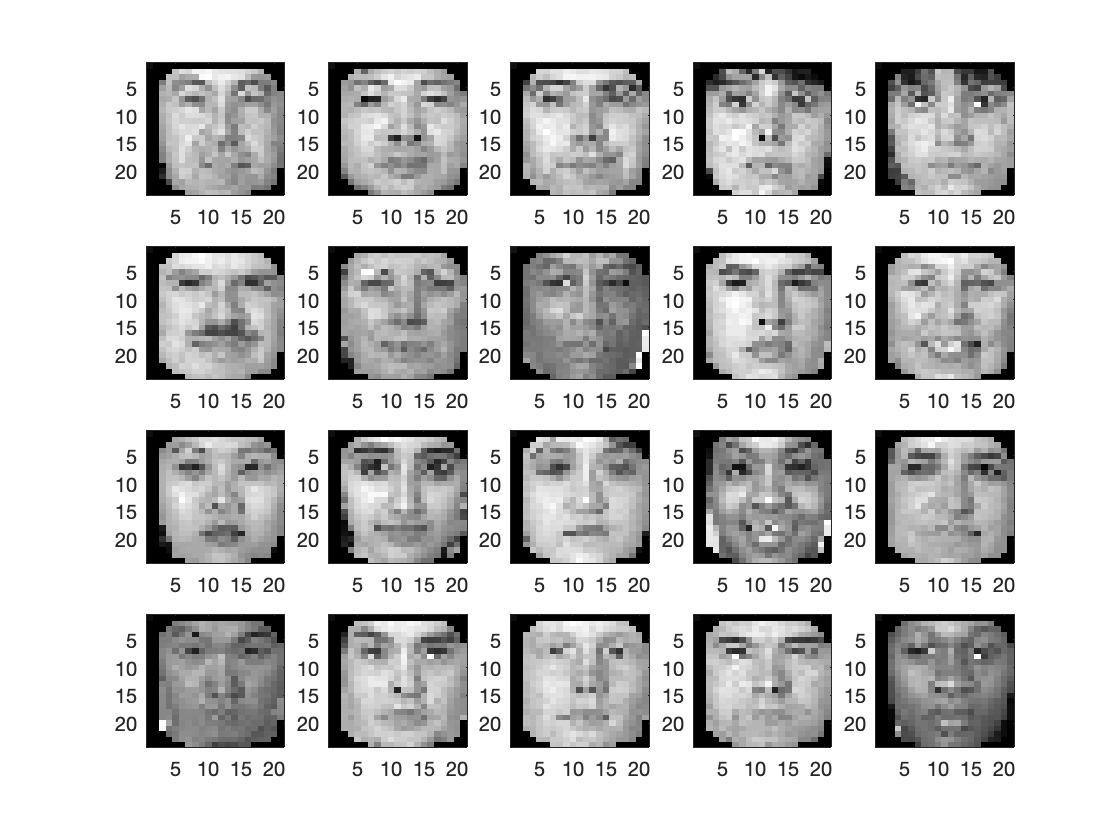

data = load('data.mat');
face = data.face;
face_neutral = face(:,:,1:3:end);
face_exp = face(:,:,2:3:end);
face_illum = face(:,:,3:3:end);
figure;
colormap gray
for j = 1 : 20
    subplot(4,5,j);
    imagesc(face_neutral(:,:,j));
end

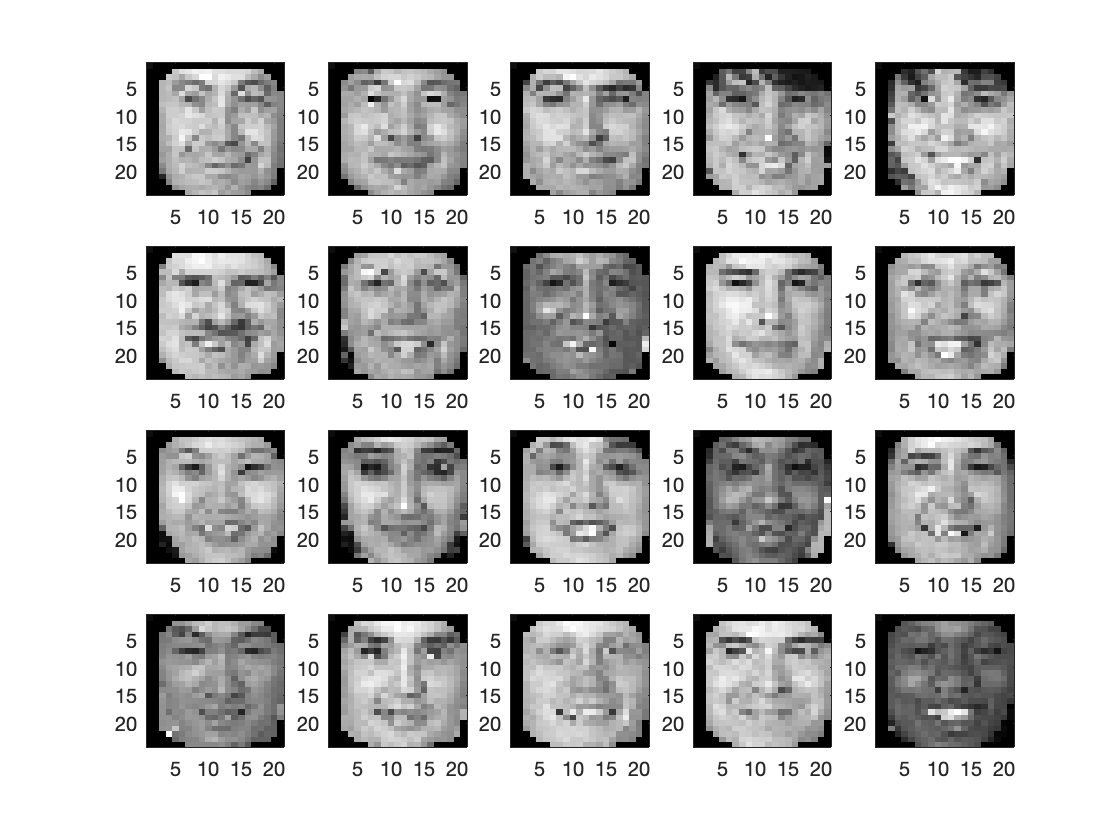

figure;
colormap gray
for j = 1 : 20
    subplot(4,5,j);
    imagesc(face_exp(:,:,j));
end

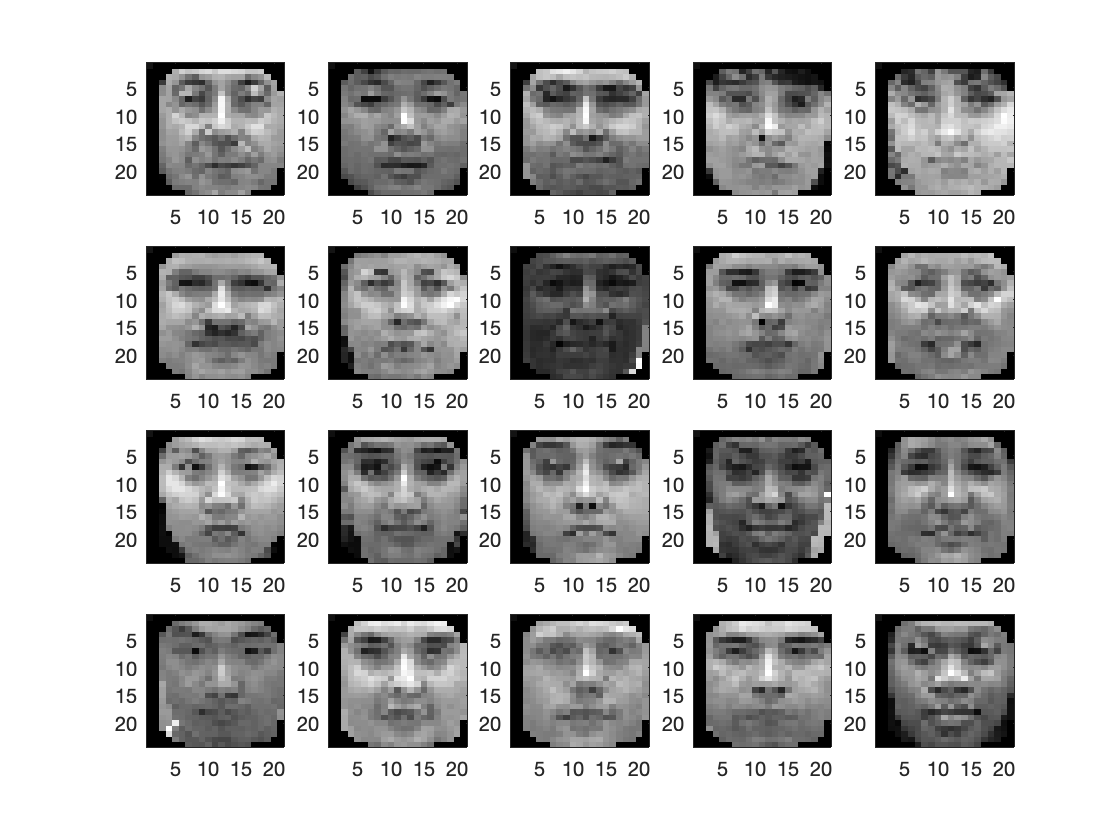

figure;
colormap gray
for j = 1 : 20
    subplot(4,5,j);
    imagesc(face_illum(:,:,j));
end

## Using PCA for Preprocessing

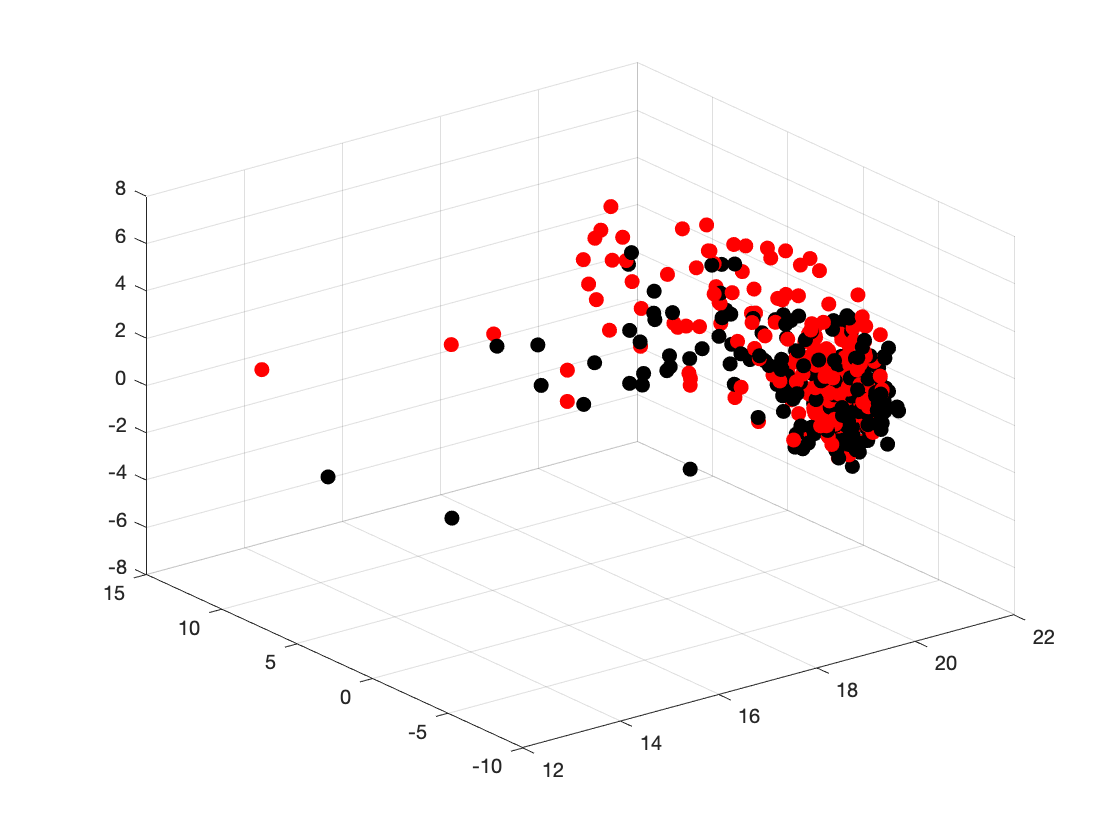

[d1,d2,n] = size(face_neutral);
X1 = zeros(n,d1*d2); % data for neutral faces
X2 = zeros(n,d1*d2); % data for smiley face

for j = 1 : n
    aux = face_neutral(:,:,j);
    X1(j,:) = aux(:)';
    aux = face_exp(:,:,j);
    X2(j,:) = aux(:)';
end

n1 = n;
n2 = n;
m1 = mean(X1,1); % column mean for X1
m2 = mean(X2,1); % column mean for X2

Xc1 = X1-ones(n1,1)*m1; % center X1
S1 = Xc1'*Xc1; % scatter matrix for X1

Xc2 = X2-ones(n2,1)*m2; % center X2
S2 = Xc2'*Xc2; % scatter matrix for X2

Sw = S1+S2; % compute matrix sw, within class scatter
Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw); % solve generalized eigenvalue problem
lam = diag(lam0);
[lam,isort] = sort(lam,'descend');

W = W(:,isort); % sort eigenvalues
w = W(:,1); % found eigenvector corresponds to the largest eigenvalue

X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;

[U,Sig,V] = svd(X', 'econ');
nPCA = 15;
% project to nPCA-dimenionsal space
Y = X*U(:,1:nPCA);
figure;
hold on;
grid;
plot3(Y(D1,1),Y(D1,2),Y(D1,3),'.','MarkerSize',20,'color','k');
plot3(Y(D2,1),Y(D2,2),Y(D2,3),'.','MarkerSize',20,'color','r');

% Show in 3D
view(3);

## Plot singular values and cumulative singular values

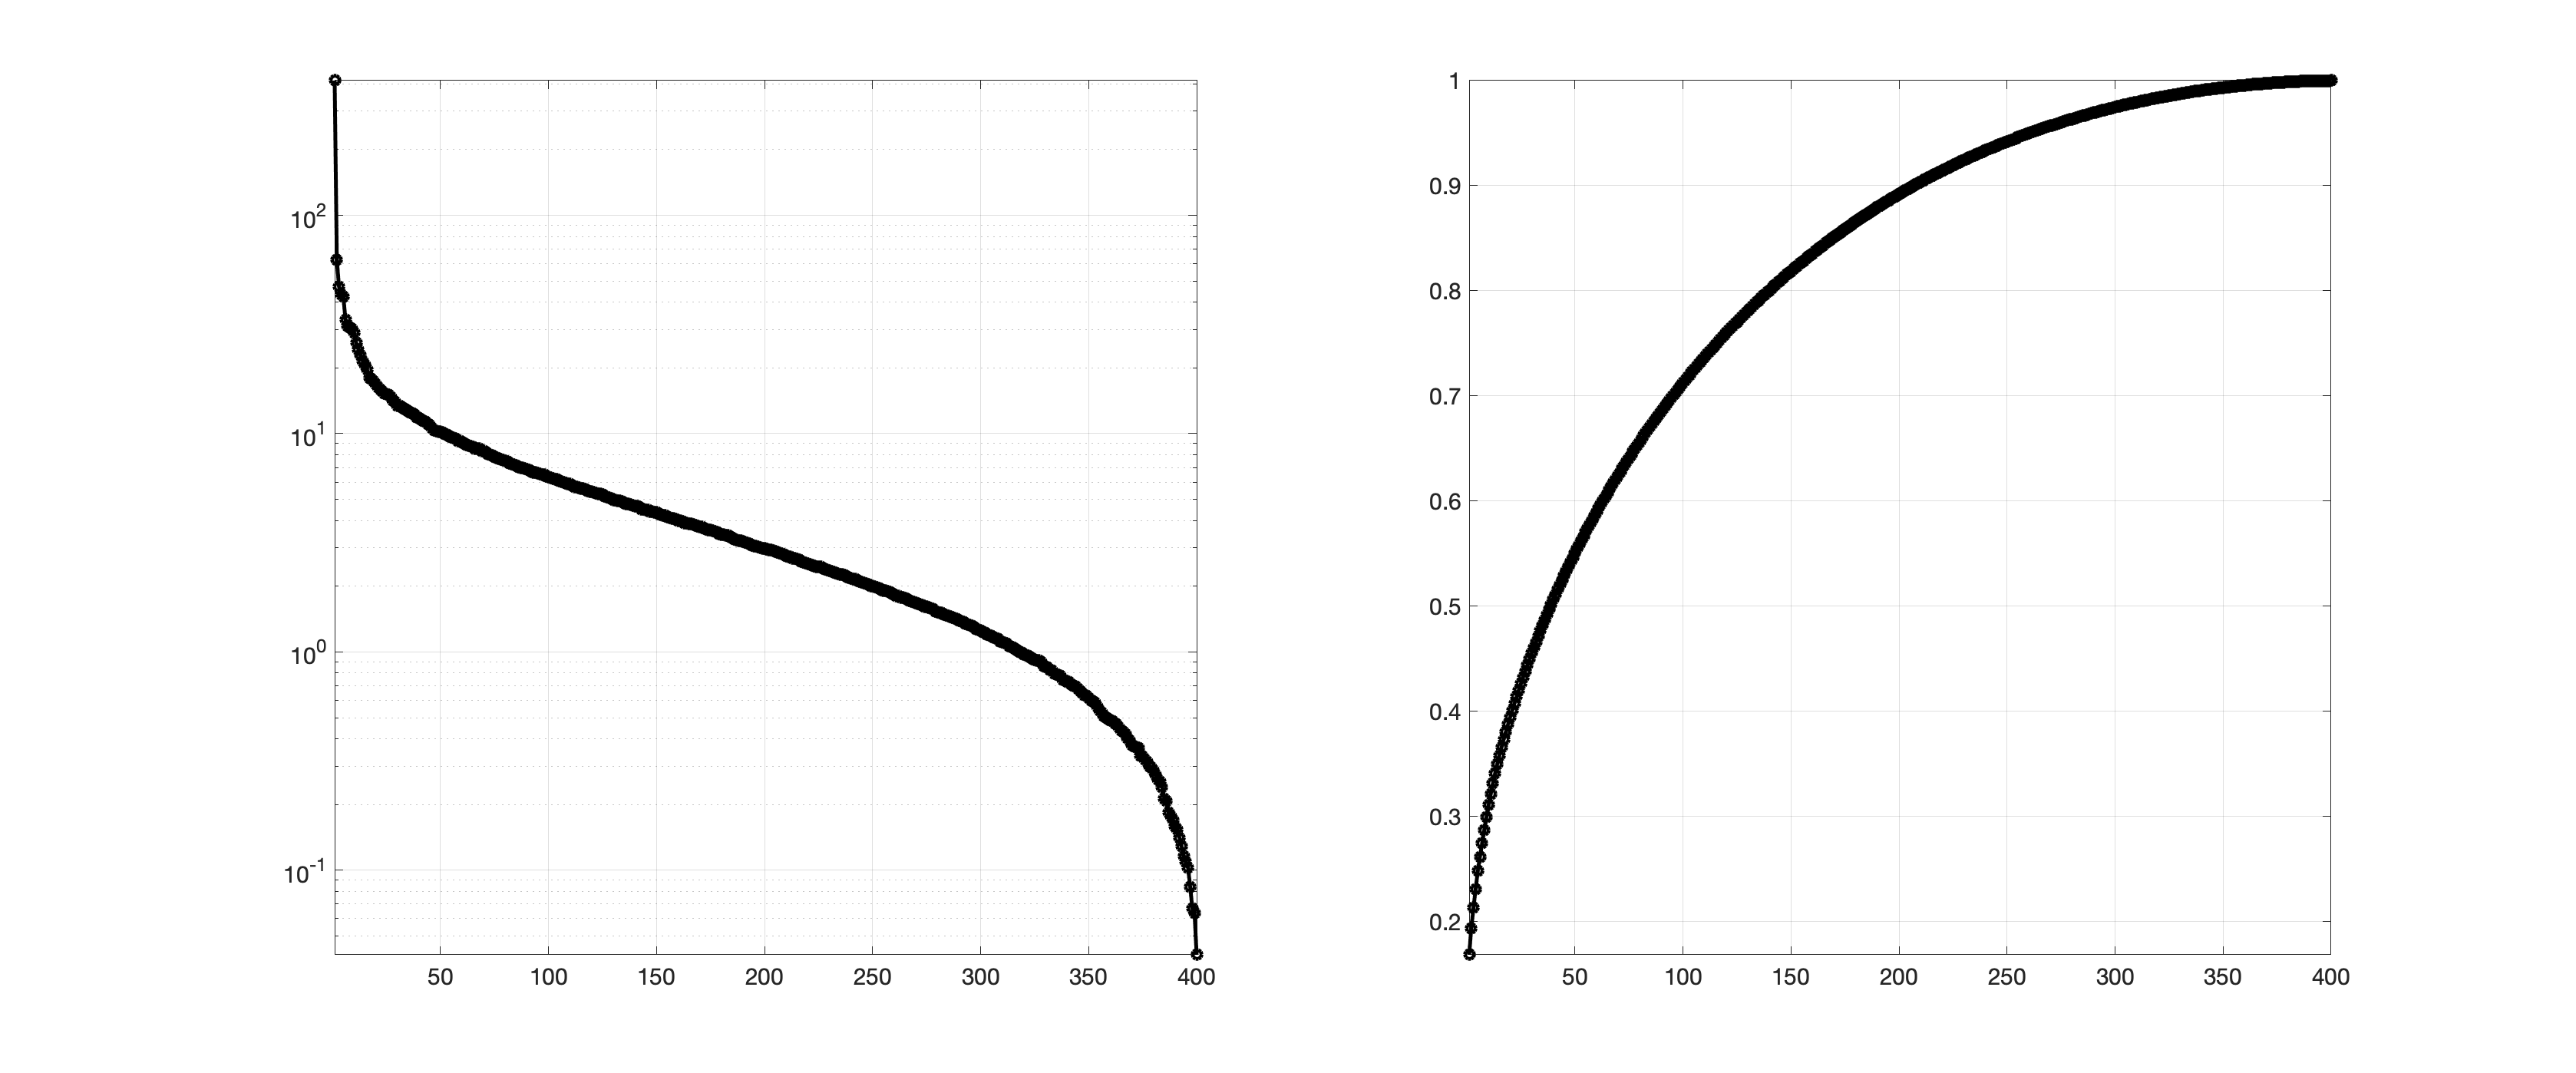

figure;
subplot(1,2,1);
semilogy(diag(Sig), 'k-o', 'LineWidth',2.5);
set(gca,'FontSize',15), axis tight, grid on;
subplot(1,2,2);
plot(cumsum(diag(Sig))./sum(diag(Sig)),'k-o','LineWidth',2.5);
set(gca,'Fontsize',15), axis tight, grid on;
set(gcf, 'Position',[1400 100 3*600 3*250]);

## Splitting Data into Train and Test Set

splitData = rand(200,504);
%rng('default');
% Cross validation (train: 70%, test: 30%)
cv = cvpartition(size(splitData,1),'HoldOut',0.3)

cv = Hold-out cross validation partition
   NumObservations: 200
       NumTestSets: 1
         TrainSize: 140
          TestSize: 60

% separate to training and test data
Ntrain = 140;
Ntest = n-Ntrain;

Label_train = categorical([ones(Ntrain,1); -ones(Ntrain,1)]);
Xtrain = zeros(d1,d2,1,Ntrain*2);
Xtrain(:,:,1,1:Ntrain) = face_neutral(:,:,1:Ntrain);
Xtrain(:,:,1,Ntrain+1:2*Ntrain) = face_exp(:,:,1:Ntrain);

Label_test = categorical([ones(Ntest,1); -ones(Ntest,1)]);
Xtest = zeros(d1,d2,1,Ntest*2);
Xtest(:,:,1,1:Ntest) = face_neutral(:,:,Ntrain+1:n);
Xtest(:,:,1,Ntest+1:2*Ntest) = face_exp(:,:,Ntrain+1:n);

## Applying PCA to training set

rng 'default'
train = rand(Ntrain);
 
train = bsxfun(@minus,train,mean(train));

[coeff,score,latent] = pca(train);

covarianceMatrix = cov(train);
[V,D] = eig(covarianceMatrix);
coeff

coeff =     0.0644    0.0711    0.1246    0.2141   -0.1515    0.0294   -0.0255   -0.0625   -0.1410    0.0518    0.0083   -0.0260   -0.0639    0.0191    0.0456    0.1128    0.0385    0.0248    0.0145    0.0591    0.0384   -0.0497   -0.0289   -0.0525    0.1492   -0.0733    0.0354    0.0011   -0.1946   -0.1692   -0.0223   -0.0166    0.0472   -0.1447    0.1842   -0.0284   -0.0177    0.0080   -0.1278   -0.1148    0.0761    0.0665    0.0846    0.1123    0.0353   -0.1598    0.0875   -0.0220    0.0932   -0.0265
   -0.1073   -0.0444    0.1533    0.0915   -0.0595   -0.1070   -0.0797   -0.0160    0.0445    0.0000   -0.0330   -0.0290   -0.0488    0.0247   -0.0089    0.0793   -0.0119   -0.0267    0.0042   -0.0855    0.0004    0.1340    0.0717    0.1026    0.0813    0.1752    0.0692   -0.0297    0.0481    0.0403   -0.0504   -0.0097   -0.1156    0.0186    0.1085   -0.0020    0.1855    0.0484   -0.0162    0.0577    0.0463    0.0299    0.1047    0.0284   -0.1316    0.0915   -0.0396    0.0124    0.1968 

V

V =     0.0812    0.0660   -0.0267   -0.0363   -0.1126   -0.1434   -0.0544   -0.0227   -0.1008    0.0978   -0.1106    0.0460   -0.0038    0.1305    0.0706   -0.0472   -0.0122    0.0424    0.0334    0.1803   -0.0525   -0.1031    0.0678   -0.0937   -0.0300   -0.1542    0.0368   -0.0003   -0.2004    0.0493    0.0180   -0.0815   -0.1904    0.0620   -0.0228   -0.0018   -0.0211    0.0015    0.0464   -0.0585    0.1014    0.0973   -0.1106   -0.0037   -0.0418   -0.0108    0.1198   -0.1109   -0.0980   -0.0756
   -0.0195   -0.0470    0.0604   -0.0653    0.0325    0.0780   -0.1553   -0.0642   -0.0067    0.1057    0.1286   -0.0089   -0.1098    0.0096   -0.0196    0.1827   -0.1491    0.1231   -0.0585   -0.0838   -0.0599   -0.1594    0.0275   -0.0302   -0.0328   -0.0082   -0.0681    0.1389   -0.0541    0.0544   -0.0104    0.0817    0.0375    0.0878    0.0348   -0.1025    0.0085    0.0700   -0.1643    0.0954   -0.0897   -0.0112    0.2274    0.0534    0.0786    0.0940   -0.0348    0.0583    0.0489   -0

dataInPrincipalComponentSpce = train*coeff

dataInPrincipalComponentSpce =     0.2766   -0.0865   -0.5940    0.7289    0.3799   -0.2147   -0.4667    0.0642   -0.8616    0.1248   -0.2054    0.7113   -0.9784    0.9545    0.0903    0.1410    0.5081   -0.2215   -0.0259   -0.3758    0.2140    0.7040    0.7177   -0.1660    0.5682   -0.2585    0.0819    0.9502    0.1119    0.1193    0.1994   -0.2457    0.5438   -0.4407    0.0318    0.2462    0.3457    0.5140    0.3448    0.1838   -0.4140    0.1970    0.2230   -0.4544    0.1985    0.6549    0.4197   -0.1640    0.3831    0.0168
   -0.4039   -0.3018    0.5645   -0.4073   -1.1216    0.3147   -0.5242   -0.0034    0.3861    0.0840    0.4562   -0.6603    0.2606   -0.0145   -0.2795    0.0431    0.0565   -0.6799    0.2401    0.5488    0.0931    0.3869    0.2892   -0.3596   -0.2757    0.3185    0.3139    0.4366    0.7930   -0.7185   -0.8085    0.3422   -0.0716   -0.5946    0.5810   -0.0654    0.0428   -0.2015   -0.0568   -0.0935    0.2052    0.0361   -0.0120    0.1043   -0.4210   -0.2332   -0.24

score

score =     0.2766   -0.0865   -0.5940    0.7289    0.3799   -0.2147   -0.4667    0.0642   -0.8616    0.1248   -0.2054    0.7113   -0.9784    0.9545    0.0903    0.1410    0.5081   -0.2215   -0.0259   -0.3758    0.2140    0.7040    0.7177   -0.1660    0.5682   -0.2585    0.0819    0.9502    0.1119    0.1193    0.1994   -0.2457    0.5438   -0.4407    0.0318    0.2462    0.3457    0.5140    0.3448    0.1838   -0.4140    0.1970    0.2230   -0.4544    0.1985    0.6549    0.4197   -0.1640    0.3831    0.0168
   -0.4039   -0.3018    0.5645   -0.4073   -1.1216    0.3147   -0.5242   -0.0034    0.3861    0.0840    0.4562   -0.6603    0.2606   -0.0145   -0.2795    0.0431    0.0565   -0.6799    0.2401    0.5488    0.0931    0.3869    0.2892   -0.3596   -0.2757    0.3185    0.3139    0.4366    0.7930   -0.7185   -0.8085    0.3422   -0.0716   -0.5946    0.5810   -0.0654    0.0428   -0.2015   -0.0568   -0.0935    0.2052    0.0361   -0.0120    0.1043   -0.4210   -0.2332   -0.2444   -0.0983    0.0134 

corrcoef(dataInPrincipalComponentSpce)

ans =     1.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   

var(dataInPrincipalComponentSpce)'

ans =     0.3090
    0.3080
    0.2950
    0.2860
    0.2786
    0.2672
    0.2633
    0.2493
    0.2411
    0.2386


latent

latent =     0.3090
    0.3080
    0.2950
    0.2860
    0.2786
    0.2672
    0.2633
    0.2493
    0.2411
    0.2386


sort(diag(D),'descend')

ans =     0.3090
    0.3080
    0.2950
    0.2860
    0.2786
    0.2672
    0.2633
    0.2493
    0.2411
    0.2386


## Applying PCA to test set

test = rand(Ntest);
 
test = bsxfun(@minus,test,mean(test));

[coeff,score,latent] = pca(test);

covarianceMatrix = cov(test);
[V,D] = eig(covarianceMatrix);
coeff

coeff =    -0.2134    0.0373   -0.0991   -0.0052   -0.0063    0.0986    0.1784   -0.0219    0.0753    0.1368   -0.0904    0.1428    0.0829   -0.0846   -0.0064   -0.0637    0.0717    0.0145    0.1204    0.1645    0.3300    0.0035   -0.2056    0.0755   -0.1904   -0.0141    0.1213    0.0039   -0.0195   -0.0764   -0.1296   -0.0536    0.1053    0.1541    0.1141   -0.1471   -0.0659    0.0007    0.0577    0.4103    0.1120   -0.1081    0.0948    0.0570    0.0435   -0.1416    0.1215    0.0942   -0.1398   -0.1301
    0.0717   -0.2128   -0.0451   -0.0746   -0.0322    0.0040    0.0940   -0.0280   -0.0033    0.0940    0.0366    0.3727    0.0663    0.3010   -0.2080    0.0432    0.0661    0.2205   -0.0250   -0.0509   -0.0051   -0.1113    0.0481   -0.0076    0.1032    0.0341    0.1758    0.0408    0.0525    0.0526    0.0545    0.0502    0.1797   -0.3065    0.0301   -0.0482   -0.0686   -0.1403   -0.0202   -0.0230    0.1579   -0.1611   -0.0748    0.0161    0.1246    0.1038   -0.2272   -0.0190   -0.1570 

V

V =     0.1255    0.0832    0.1896    0.1392    0.0115    0.0268    0.2607    0.1462    0.1156   -0.0604   -0.1301   -0.1398   -0.0942   -0.1215   -0.1416   -0.0435    0.0570   -0.0948   -0.1081   -0.1120    0.4103    0.0577   -0.0007   -0.0659    0.1471   -0.1141    0.1541    0.1053    0.0536   -0.1296    0.0764    0.0195   -0.0039   -0.1213   -0.0141    0.1904    0.0755    0.2056    0.0035   -0.3300    0.1645    0.1204    0.0145   -0.0717    0.0637   -0.0064   -0.0846    0.0829   -0.1428    0.0904
   -0.0262    0.0821   -0.2156   -0.0421    0.0189   -0.2092    0.1464    0.1357   -0.2081   -0.1220   -0.0591   -0.1570    0.0190    0.2272    0.1038   -0.1246    0.0161    0.0748   -0.1611   -0.1579   -0.0230   -0.0202    0.1403   -0.0686    0.0482   -0.0301   -0.3065    0.1797   -0.0502    0.0545   -0.0526   -0.0525   -0.0408   -0.1758    0.0341   -0.1032   -0.0076   -0.0481   -0.1113    0.0051   -0.0509   -0.0250    0.2205   -0.0661   -0.0432   -0.2080    0.3010    0.0663   -0.3727   -0

dataInPrincipalComponentSpce = test*coeff

dataInPrincipalComponentSpce =     0.2777   -0.3224    0.4922   -0.7481   -0.5076    0.3371    0.7891    0.0288   -0.3384    0.4802   -0.6397    0.3112    0.5446    0.2734   -0.8019    0.2340   -0.1553   -0.1162    0.2039    0.5645    0.0418   -0.3781    0.0675    0.0124   -0.0598   -0.1034   -0.1722   -0.4865    0.3013    0.0616    0.0304   -0.0793    0.4495    0.2964    0.0313   -0.0850   -0.1702    0.1708    0.1244    0.2136   -0.1014   -0.1006   -0.0182   -0.1064   -0.0023    0.0545    0.0861    0.0028   -0.1472    0.1211
   -0.1587   -0.3704   -0.0620   -0.3375    0.2238   -0.5932   -0.2726   -0.2754   -0.1614    0.1159    0.2499    0.0826    0.0210    0.3009    0.4689   -0.7166    0.0276   -0.6249   -0.0516    0.3661    0.0352    0.1645   -0.2436   -0.5617    0.3891   -0.1437   -0.2199    0.3706   -0.0322    0.0513    0.1566   -0.2130   -0.1522   -0.2656   -0.4266   -0.1055   -0.1154   -0.2076    0.2075   -0.0894   -0.1568    0.1756   -0.1485   -0.0829   -0.1310    0.0104    0.05

score

score =     0.2777   -0.3224    0.4922   -0.7481   -0.5076    0.3371    0.7891    0.0288   -0.3384    0.4802   -0.6397    0.3112    0.5446    0.2734   -0.8019    0.2340   -0.1553   -0.1162    0.2039    0.5645    0.0418   -0.3781    0.0675    0.0124   -0.0598   -0.1034   -0.1722   -0.4865    0.3013    0.0616    0.0304   -0.0793    0.4495    0.2964    0.0313   -0.0850   -0.1702    0.1708    0.1244    0.2136   -0.1014   -0.1006   -0.0182   -0.1064   -0.0023    0.0545    0.0861    0.0028   -0.1472    0.1211
   -0.1587   -0.3704   -0.0620   -0.3375    0.2238   -0.5932   -0.2726   -0.2754   -0.1614    0.1159    0.2499    0.0826    0.0210    0.3009    0.4689   -0.7166    0.0276   -0.6249   -0.0516    0.3661    0.0352    0.1645   -0.2436   -0.5617    0.3891   -0.1437   -0.2199    0.3706   -0.0322    0.0513    0.1566   -0.2130   -0.1522   -0.2656   -0.4266   -0.1055   -0.1154   -0.2076    0.2075   -0.0894   -0.1568    0.1756   -0.1485   -0.0829   -0.1310    0.0104    0.0518    0.0411    0.0097 

corrcoef(dataInPrincipalComponentSpce)

ans =     1.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   

var(dataInPrincipalComponentSpce)'

ans =     0.3166
    0.2951
    0.2859
    0.2583
    0.2459
    0.2429
    0.2081
    0.2030
    0.1962
    0.1854


latent

latent =     0.3166
    0.2951
    0.2859
    0.2583
    0.2459
    0.2429
    0.2081
    0.2030
    0.1962
    0.1854


sort(diag(D),'descend')

ans =     0.3166
    0.2951
    0.2859
    0.2583
    0.2459
    0.2429
    0.2081
    0.2030
    0.1962
    0.1854


## Apply Bayesian Decision Theory using training set

Y1 = Y(D1,:); % projected data of neutral class
Y2 = Y(D2,:); % projected data of smily class
mu1 = mean(Y1,1); % column mean of Y1
mu2 = mean(Y2,1); % column mean of Y2
fprintf('norm(mu1-mu2) = %d\n',norm(mu1-mu2)); % print mu1,mu2

norm(mu1-mu2) = 3.208607e+00


% estimate covariance matrices for each class
% center data in each class to compute covariance matrices
Y1c = Y1-ones(n1,1)*mu1; % centering the data in class1
Y2c = Y2-ones(n2,1)*mu2; % centering the data in class2
S1 = Y1c'*Y1c/n1; % compute first covariance matrix
S2 = Y2c'*Y2c/n2; % compute second covariance matrix

## visualization of first covariance matrix

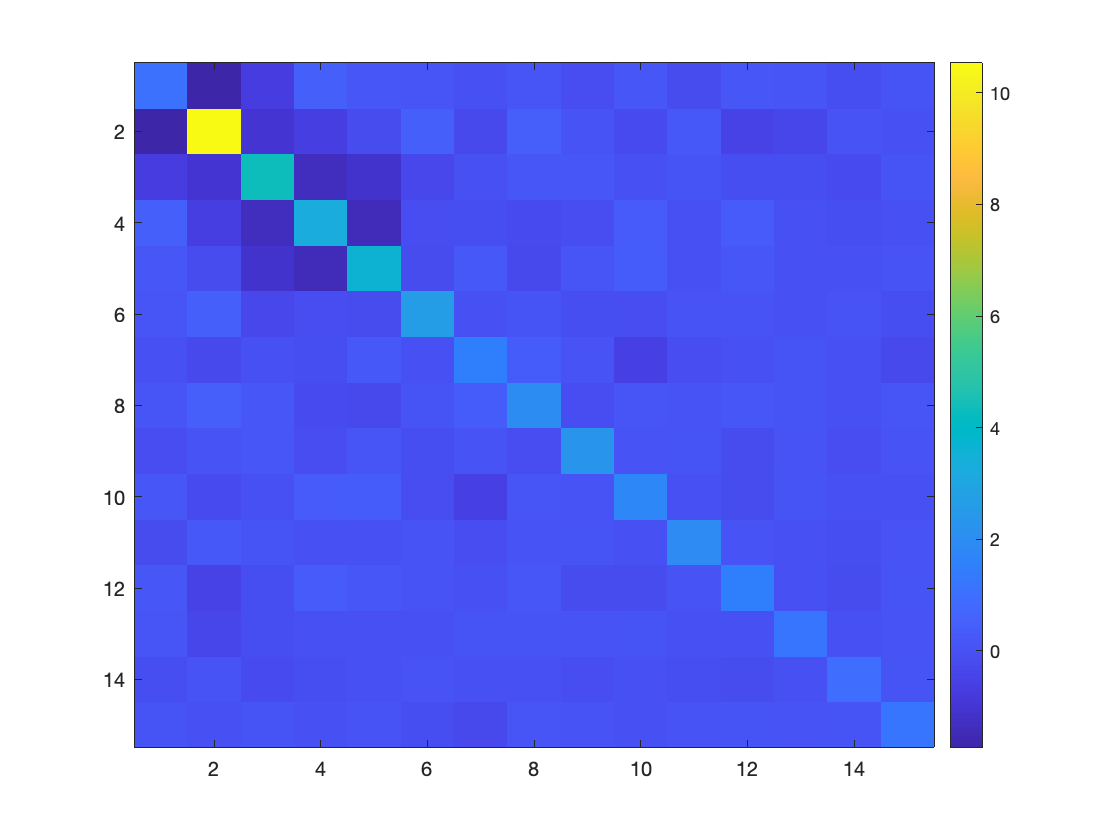

figure;
imagesc(S1);
colorbar;

## visiualization of second covariance matrix

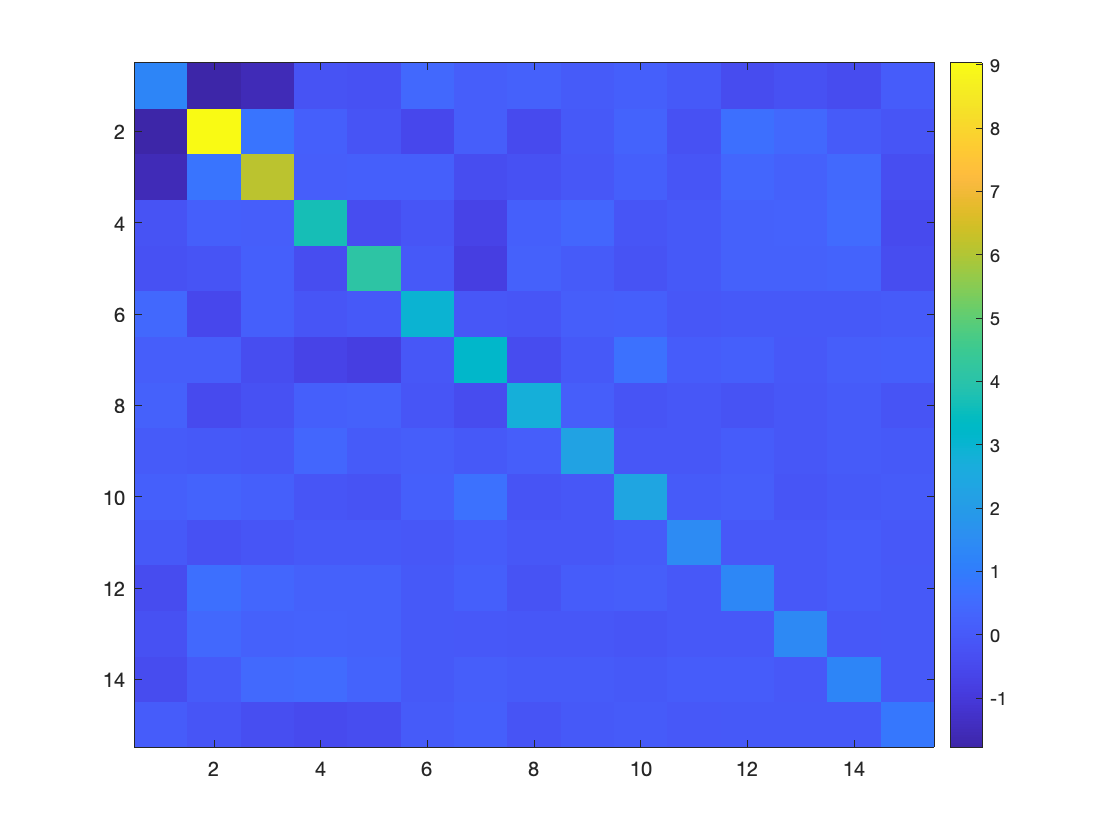

figure;
imagesc(S2);
colorbar;

## Define the discriminant functions

iS1 = inv(S1);
iS2 = inv(S2);
mu1 = mu1';
mu2 = mu2';
w0 = 0.5 * (log(det(S2)/det(S1))) - 0.5*(mu1'*iS1*mu1 - mu2'*iS2*mu2);
g = @(x)-0.5*x'*(iS1-iS2)*x + x'*(iS1*mu1-iS2*mu2) + w0;

## classify the neutral faces and smiley faces

Y1 = zeros(n,nPCA);
label = zeros(n,1);
for j = 1 : n
    aux = face_neutral(:,:,j);
    y = (aux(:)'*U(:,1:nPCA))';
    Y1(j,:) = y';
    label(j) = sign(g(y));
end
iplus = find(label > 0);
iminus = find(label < 0);
fprintf('#iplus = %d, #iminus = %d\n',length(iplus),length(iminus));

#iplus = 189, #iminus = 11


Y2 = zeros(n,nPCA);
label = zeros(n,1);
for j = 1 : n
    aux = face_exp(:,:,j);
    y = (aux(:)'*U(:,1:nPCA))';
    Y2(j,:) = y';
    label(j) = sign(g(y));
end
iplus = find(label < 0);
iminus = find(label > 0);
fprintf('#iplus = %d, #iminus = %d\n',length(iplus),length(iminus));

#iplus = 173, #iminus = 27


## Apply k-NN using test data

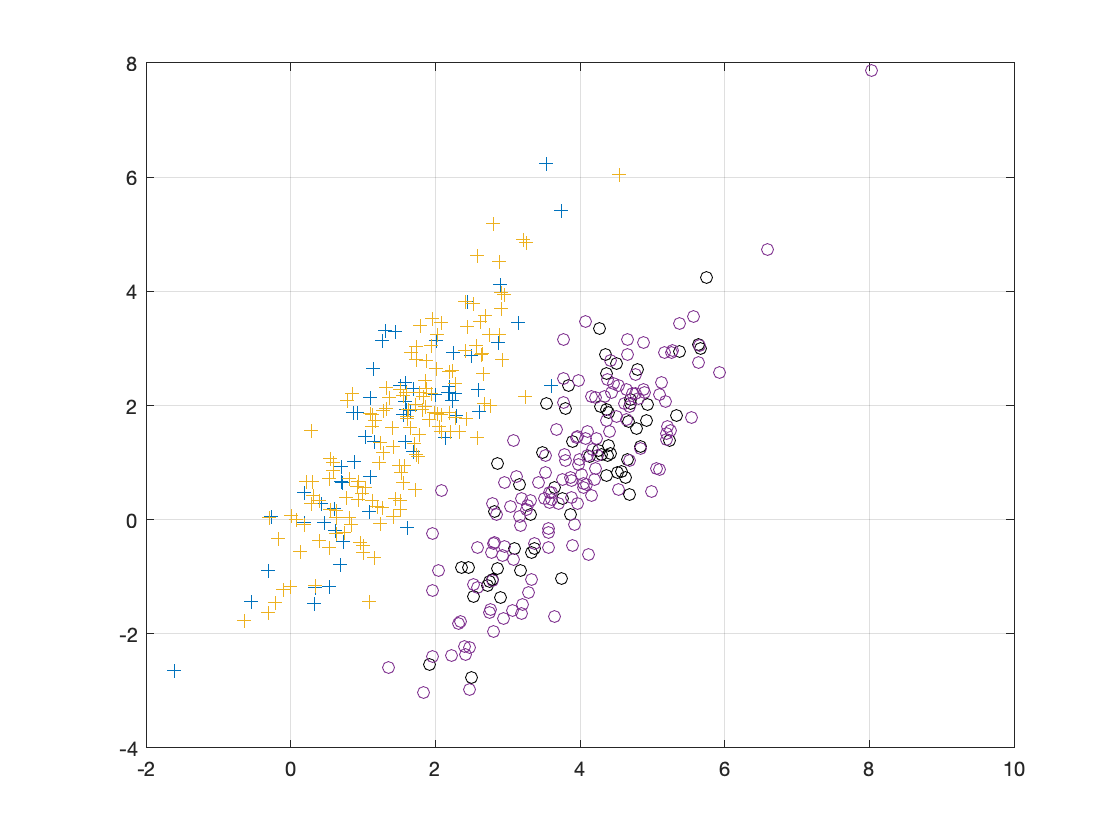

% Forming and plotting the dataset
mu = [1.5,1.5]; sigma = [1,1.5;1.5,3];
sampleNo = 200;
testNo = 60;
C1X = (mvnrnd(mu,sigma,sampleNo))';
mu = [4,1];sigma = [1,1.5;1.5,3];
C2X = (mvnrnd(mu,sigma,sampleNo))';
% mean computation
x = [C1X,C2X];
y1 = zeros(1,sampleNo);
y2 = ones(1,sampleNo);
y = [y1,y2];
test_x   = [C1X(:,1:testNo),C2X(:,1:testNo)];
train_x  = [C1X(:,testNo+1:sampleNo),C2X(:,testNo+1:sampleNo)];
test_y = [y1(:,1:testNo),y2(:,1:testNo)];
train_y  = [y1(:,testNo+1:sampleNo),y2(:,testNo+1:sampleNo)];

% see the dataset 
plot(C1X(1,1:testNo),C1X(2,1:testNo),'+'); 
hold on; 
grid on;      
plot(C2X(1,1:testNo),C2X(2,1:testNo),'ko');

plot(C1X(1,testNo+1:sampleNo),C1X(2,testNo+1:sampleNo),'+'); 
hold on; 
grid on;  
plot(C2X(1,testNo+1:sampleNo),C2X(2,testNo+1:sampleNo),'o');

knn_loop(test_x,train_x,2);

function test_data = knn_loop(test_data, tr_data,k)

numoftestdata = size(test_data,1);
numoftrainingdata = size(tr_data,1);

    for sample=1:numoftestdata

       %Step 1: Computing euclidean distance for each testdata
       R = repmat(test_data(sample,:),numoftrainingdata,1) ;
       euclideandistance  = (R(:,1) - tr_data(:,1)).^2;

       %Step 2: compute k nearest neighbors and store them in an array
        [dist position] = sort(euclideandistance,'ascend');
        knearestneighbors=position(1:k);
        knearestdistances=dist(1:k);


        % Step 3 : Voting 
        for i=1:k
            A(i) = tr_data(knearestneighbors(i),2);  
        end

        M = mode(A);

        if (M~=1)
            test_data(sample,2) = mode(A);
        else 
            test_data(sample,2) = tr_data(knearestneighbors(1),2);
        end
    end
end

function out_data = knn_vector(test_data,tr_data,k)
    test_data_n = size(test_data,1);
    tr_data_n = size(tr_data,1);

    % absolute distance between all test and training data
    dist = abs(repmat(test_data,1,tr_data_n) - repmat(tr_data(:,1)',test_data_n,1));

    % indicies of nearest neighbors
    [~,nearest] = sort(dist,2);
    % k nearest
    nearest = nearest(:,1:k);

    % mode of k nearest
    val = reshape(tr_data(nearest,2),[],k);
    out_data = mode(val,2);
    % if mode is 1, output nearest instead
    out_data(out_data==1) = val(out_data==1,1);
end






